# **LSM710 Simulated Confocal: Laser Study**

#### **Here, we will model the Zeis LSM710 confocal microscope, studying how laser power can be modified to change the overall FOM.**

In particular, we will show a model setup where alexa 488, 568, and 647 are imaged using the 488/561/647 MBS that come standard with the Zeiss 710.

#### Model Components: 

- Fluorescence Filters: 488/561/647 MBS

- Lasers:  Argon, (488 nm, 25mW) | HeNe (561 nm, 20mW) | HeNe2 (633 nm, 5mW).

- Detectors: 34 channels, 9.8nm wide

- Fluorophore spectra (ThermoFisher) (Alexa 488, 567, 647)

**Importing features**

%I first downloaded a 488/561/647 MBS excel sheet from ? (long time ago)

**Filter**

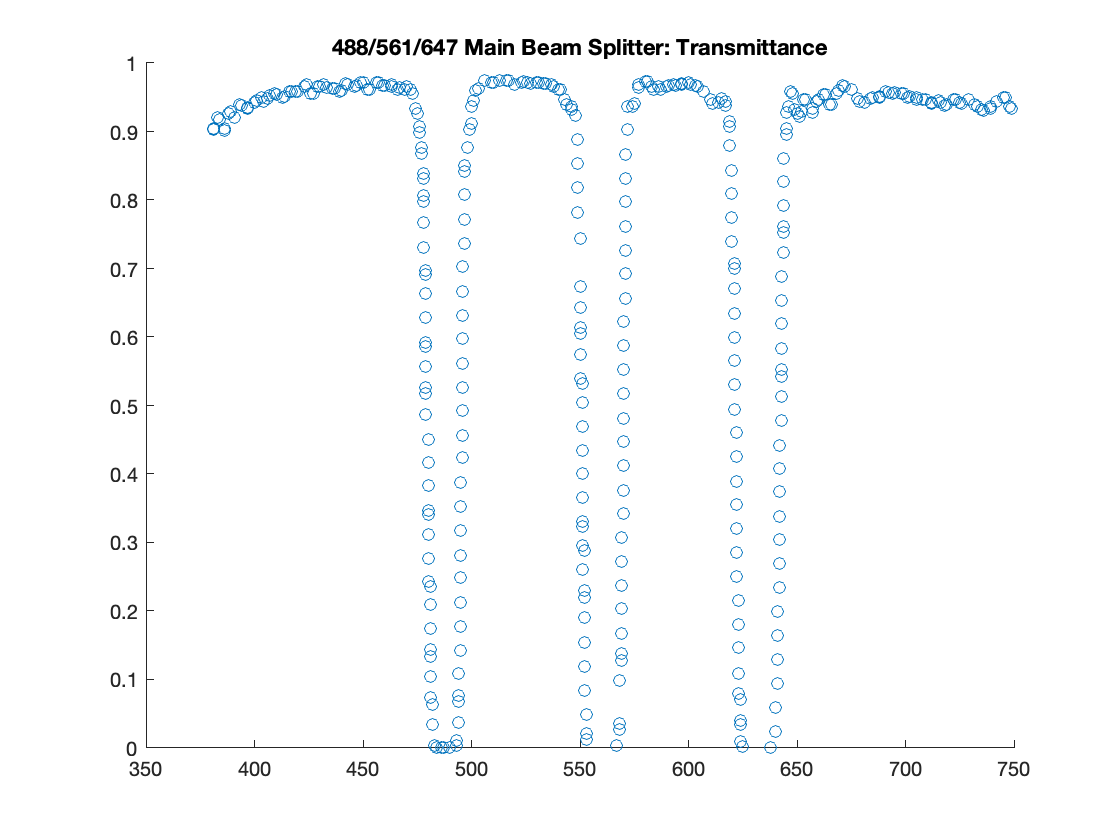

filterSpectra = readmatrix('/assets/MBSZeiss.csv'); %import filter spectra into matrix

%VISUAL:
scatter(filterSpectra(:,1), filterSpectra(:,2)) 
title("488/561/647 Main Beam Splitter: Transmittance")
ylim([0 1])

**Lasers**

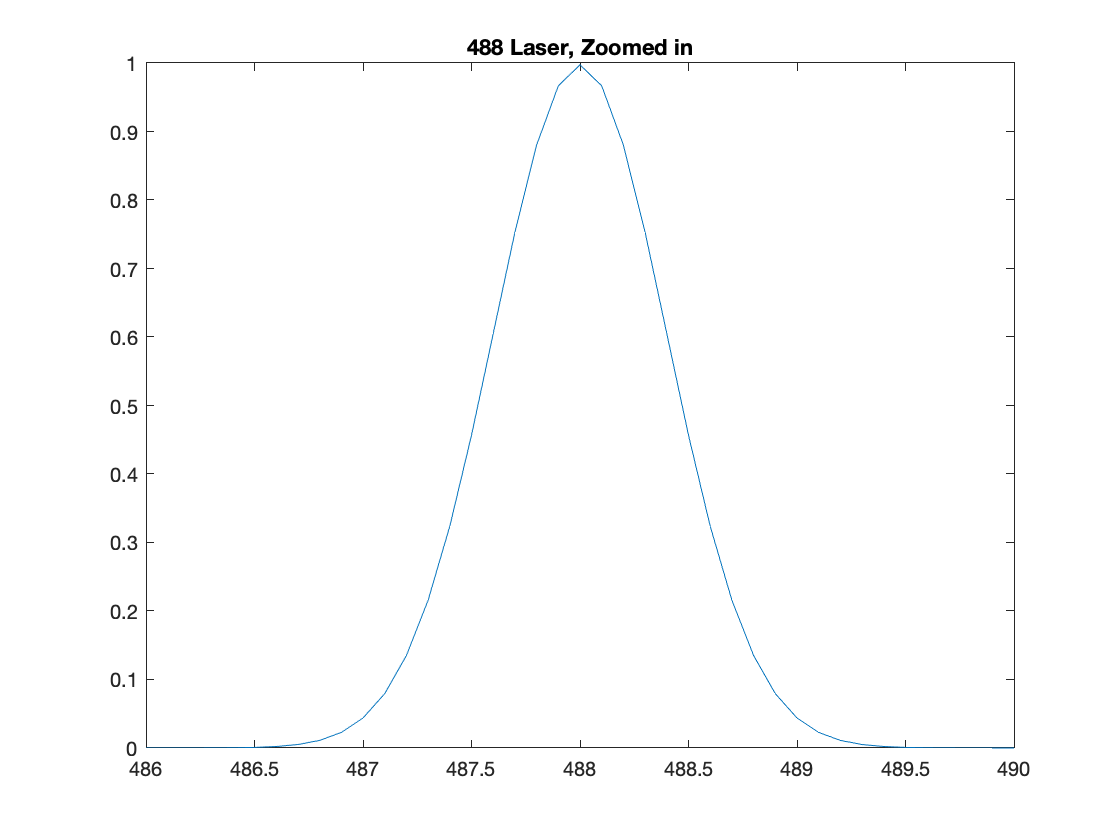

%let's generate these lasers:

wavelengths = [488 561 633]; %What lasers do we want to use?


lasers = makeLaser(wavelengths); %this function can found as "makeLaser.m" in functions

%what do the lasers look like?
%488 laser looks like:
plot(lasers(:,1,1),lasers(:,2,1))
title('488 Laser, Zoomed in')

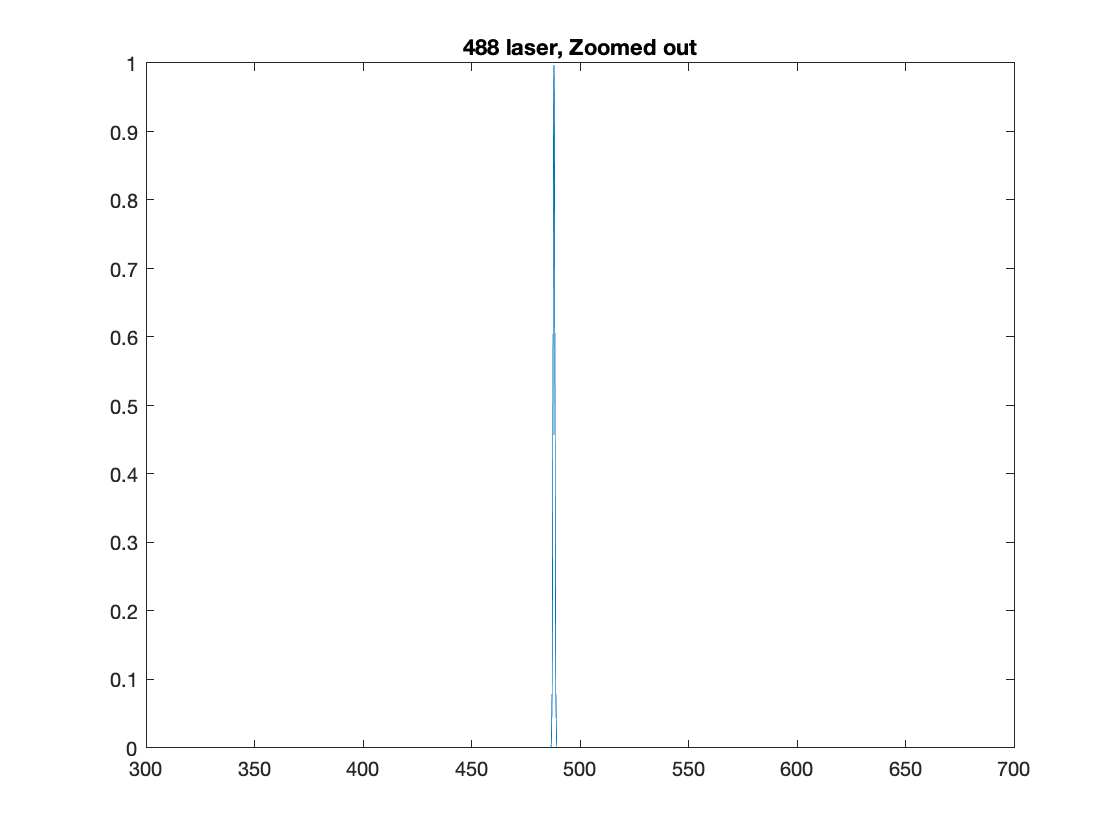



plot(lasers(:,1,1),lasers(:,2,1)) %this is the same laser as before
xlim([300 700])                    %just changed the x-range to zoom out.
title('488 laser, Zoomed out')

**Detector**

%The detector is just modeled as a 34 channel, 9.8nm wide array. This will
%become more clear later.

detector = 400:9.8:733.2;

%here, 400 is the beginning of channel 1, and 733.2 is the end of channel
%34


**Fluorophores**

%let's iterate through assets and collect our fluorophores

d = dir("assets/Alexa*"); %this pulls all the filenames with "alexa" into a struct

fluors = struct;% I'm going to put my fluorophores in a structure

for k = 1:length(d)                            %iterate through all the alexa fluors I have
    fluors(k).('name') = d(k).name;             %store their name in a structure
    fluors(k).('Spectra') = readmatrix(d(k).name); %then store their spectra in the stucture
end

fluors

fluors = 1×3 struct array with fields:
    name
    Spectra


**All our components are collected. **

**To model this system, we will start with the ****lasers****, which excite the fluorophores according to their excitation spectra. **

**First, we have to combine the lasers and fit them to our detector range.**

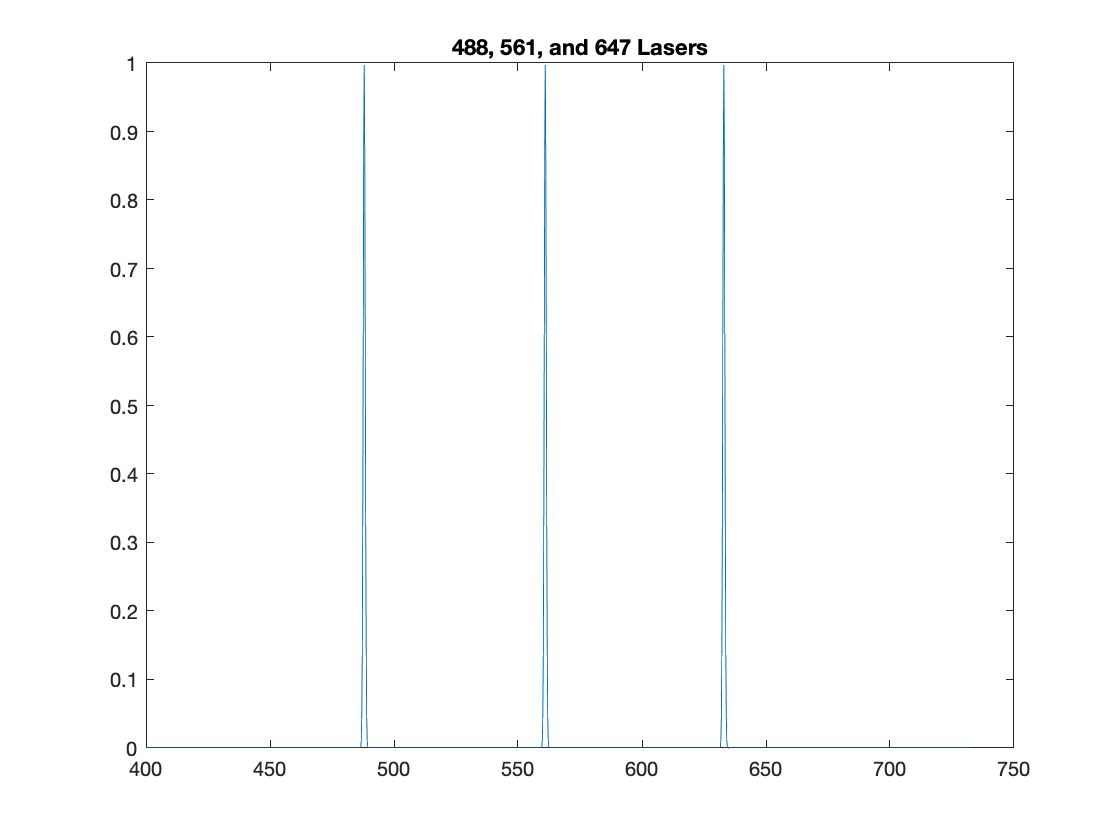

%the lasers are defined at a 0.1 nm resolution. To fit them to our
%detector and fluors, we have to downsample them to a 0.2nm resolution.

fitRange = (400:0.2:733.2)'; %this is our wavelength range for everything to fit to

laser488 = interp1(lasers(:,1,1),lasers(:,2,1),fitRange,"linear","extrap");
laser488(laser488<0) = 0;

laser561 = interp1(lasers(:,1,2),lasers(:,2,2),fitRange,"linear","extrap");
laser561(laser561<0) = 0; 

laser647 = interp1(lasers(:,1,3),lasers(:,2,3),fitRange,"linear","extrap");
laser647(laser647<0) = 0;

%Now the 3 lasers are formatted to one another, we can simply add them
%together:

lasersCombined = laser488 + laser561 + laser647;

%Now we can plot all three on the pertinent range:
l = figure;
plot(fitRange, lasersCombined)
title("488, 561, and 647 Lasers")

**Next, we have to format our fluorophores to fit this range in a similar way**

**I'm going to store the excitation and emission spectra in separate fields for each fluorophore. You'll see in a second**

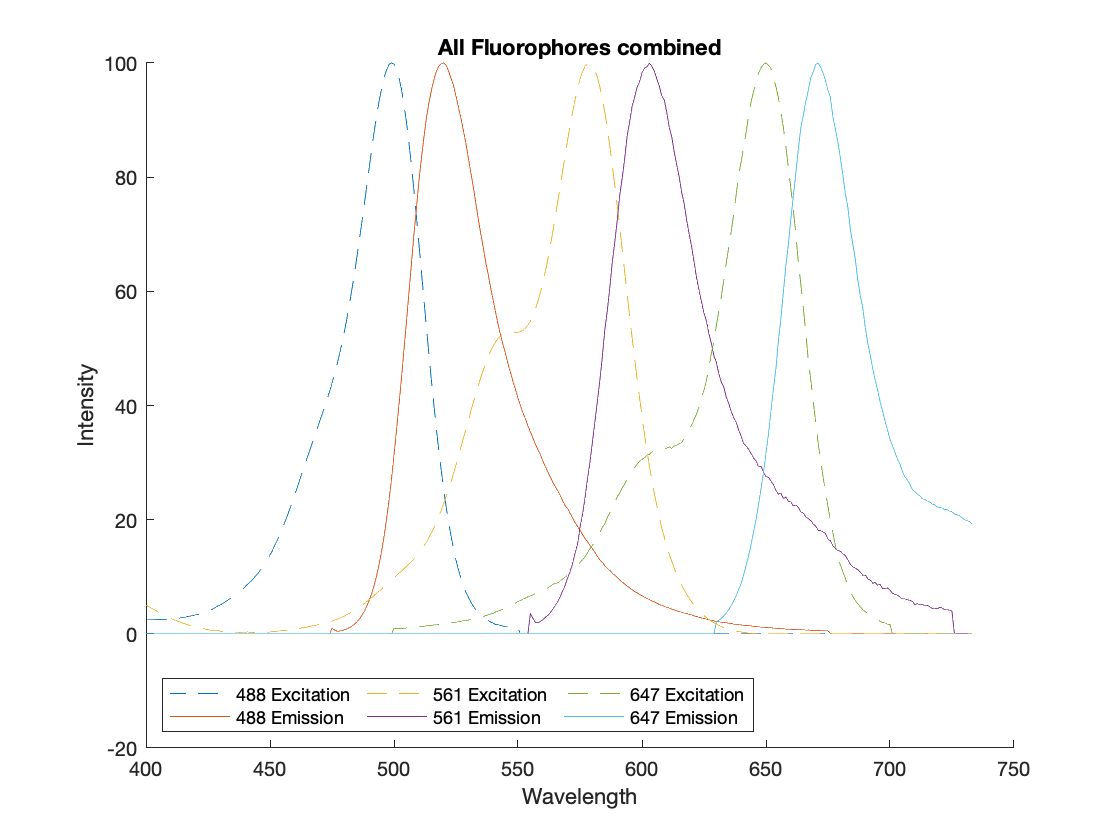



displayNameEx = ["488 Excitation","561 Excitation", "647 Excitation"]; %these are just labels for the plot
displayNameEm = ["488 Emission", "561 Emission", "647 Emission"];

s = figure;
hold on %just graphing stuff

for k = 1:length(fluors) %This loop will interpolate and extrapolate on the fluorophore spectra, fitting it to our range
    fluors(k).('ex') = interp1(fluors(k).Spectra(:,1),fluors(k).Spectra(:,2),fitRange,"linear","extrap"); %excitation side
    fluors(k).('em') = interp1(fluors(k).Spectra(:,1),fluors(k).Spectra(:,3),fitRange,"linear","extrap"); %emission side
    plot(fitRange, fluors(k).ex,'--','DisplayName', displayNameEx(k))
    plot(fitRange, fluors(k).em, 'DisplayName', displayNameEm(k))
end


legend('location', 'southwest','NumColumns',3) %more graphing stuff
title("All Fluorophores combined")
ylabel("Intensity")
xlabel("Wavelength")

**Splendid. Lastly, we have to format our filter to the same range.**

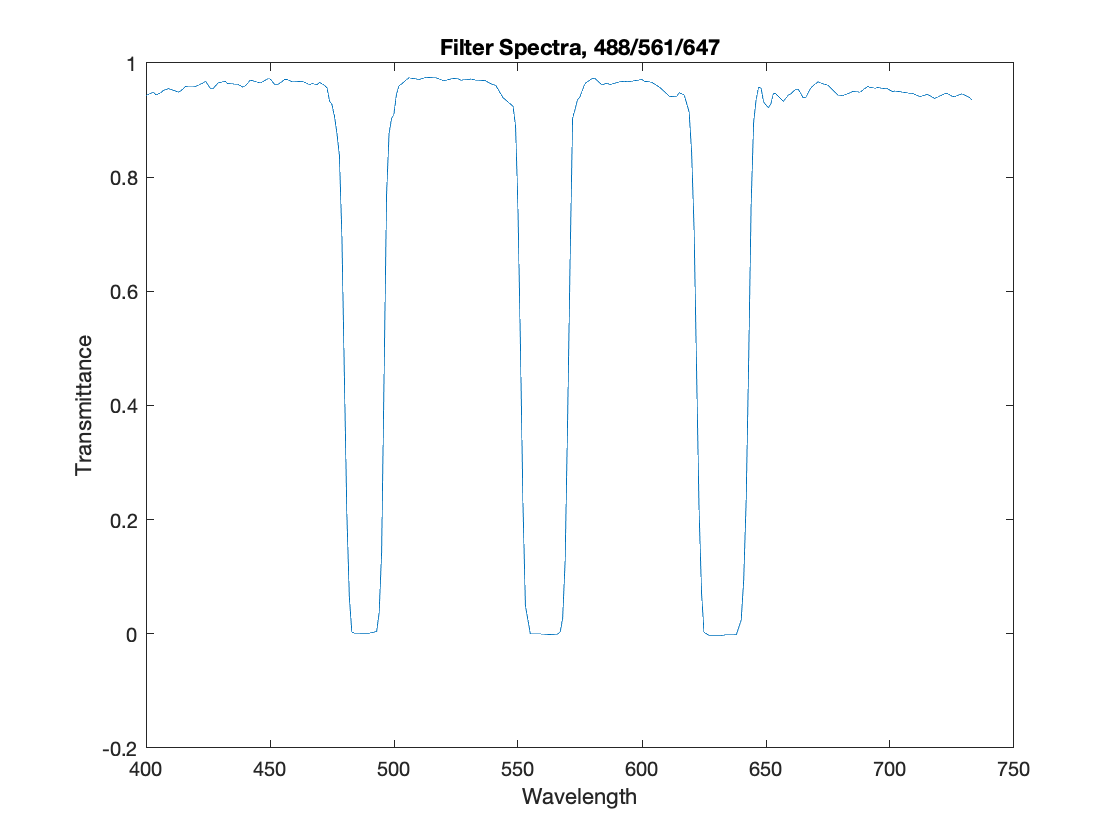

%first we have to clean up the filterSpectra
[c, ia, ic] = unique(filterSpectra(:,1)); %this just removes duplicate values in the filter spectrum
filterSpectraClean = filterSpectra(ia,:); %this stores those clean values in a variable

fitfilterSpectra = interp1(filterSpectraClean(:,1),filterSpectraClean(:,2),fitRange,"linear", "extrap"); %this is fitting the filter spectrum to our range
figure
plot(fitRange, fitfilterSpectra)
title("Filter Spectra, 488/561/647")
xlabel("Wavelength")
ylabel("Transmittance")